I = imread("car2.jpg");
I = rgb2gray(I);
I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
imshow(I);
hold on;
plot(sift.selectStrongest(3))
num = sift.selectStrongest(1)

num =   SIFTPoints with properties:

          Scale: 3.4358
    Orientation: 0
         Octave: 0
          Layer: 3
       Location: [206.2893 15.1828]
         Metric: 0.0942
          Count: 1


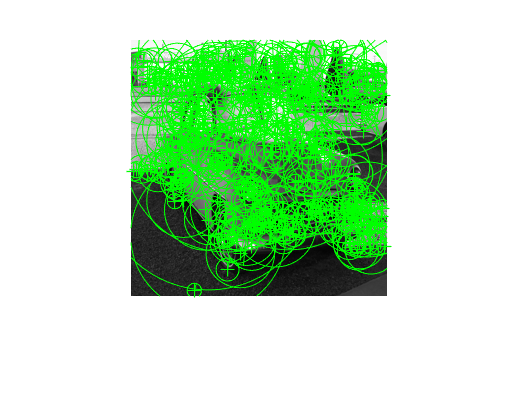

[features, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);

Reading images from dataset

% if we need to load more data types, in imagefiles add
% ;dir('*.[datatype extension]')
% note that after we cd to a lower folder, we must do cd('..\')
% to navigate up back to our original location
cd('folder_name'); % replace with the actual folder name

imagefiles = [dir('*.jpg');dir('*.png')];      
nfiles = length(imagefiles);    % Number of files found
for ii=1:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(currentfilename);
   images{ii} = currentimage;
   figure,imshow(currentimage);
end

cd('..\');

% X = dataset of images
F = []


F =

     []



ref = []


ref =

     []




% preprocess the images and collect their SIFT features into a matrix
for i = 1:length(X)
    I = rgb2gray(imread(X(i)));
    I = imresize(I, [256 256]);
    sift = detectSIFTFeatures(I);
    [features, sift_points] = extractFeatures(I, sift);
    features = rot90(features);
    F = [F features]
    ref = [ref; repmat([i], 1, length(F))]
end

Unrecognized function or variable 'X'.


% construct LSH hash tables for F

Q = 1000; % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 2;    % # of tables
M = 10;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(X, L, M, W);




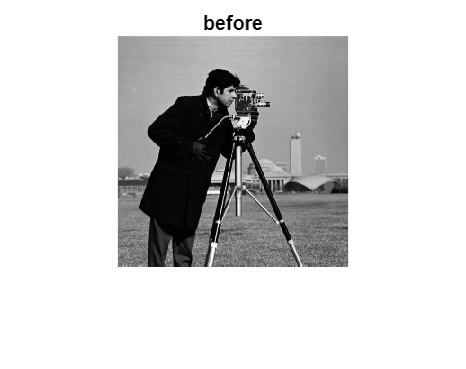

% query for image
% query = image
I = imread(query);

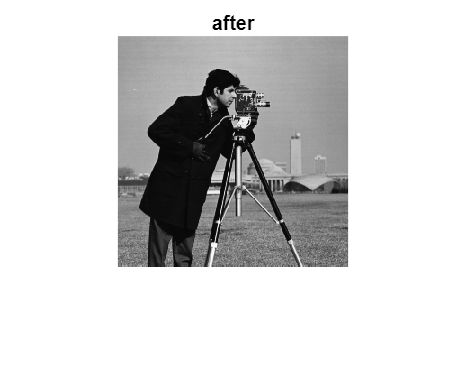

% check if it is not already grey scale
if size(I,3)==3
    I = rgb2gray(I);
end

I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
[features, sift_points] = extractFeatures(I, sift);
Qfeatures = rot90(features);




% Perform simple LSH search on the first Q elements of X
[idsSIMPLE, cand_sizeSIMPLE, binsFound_ratiosSIMPLE] = lshSearch(Qfeatures, X, lshStruct, K);
% is the same with: [idsSIMPLE cand_sizeSIMPLE binsFound_ratiosSIMPLE] = lshSearch(X(:, 1:Q), X, lshStruct, K, 0);

% Perform multiprobe LSH search on the first Q elements of X
[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(X(:, 1:Q), X, lshStruct, K, T);

% Perform brute force KNN on the first Q elements of X
% [~, idsTRUE] = knn(X(:, 1:Q), X, K);

% Compute recalls
% recallSIMPLE = compute_recall(idsTRUE, idsSIMPLE);
% recallMULTIPROBE = compute_recall(idsTRUE, idsMULTIPROBE);

% Compute selectivities (i.e. mean size of distinct candidates for each query)
% selectivitySIMPLE = sum(cand_sizeSIMPLE) / (Q * size(X, 2));
% selectivityMULTIPROBE = sum(cand_sizeMULTIPROBE) / (Q * size(X, 2));
